## Guião 4

### Exercicio 1

- **Estados (BER):** $10^{-6}$, $
10^{-5}
$, $
10^{-4}

$, $10^{-3}

$, $10^{-2}$ 

- **Taxas de "nascimento" (**$\lambda_i$**)** (avançar para um BER superior): 600, 100, 20, 5 

- **Taxas de "morte" (**$\mu_i$**)** (recuar para um BER inferior): 8, 5, 2, 1 

(a) Determine the probability of the link being on each state. 

    O Exercício 1 descreve um **Processo de Nascimento e Morte**. Este é o nome dado a sistemas cujos estados avançam ou recuam apenas um passo de cada vez.

    Para este exercício, os nossos estados da Taxa de Erros de Bit (BER) sao:

- **Estado 0:** $10^{-6}$

- **Estado 1:** $
10^{-5}
$

- **Estado 2:** $
10^{-4}

$

- **Estado 3:** $10^{-3}

$

- **Estado 4:** $10^{-2}$

    As taxas de transição entre estes estados têm dois nomes:

- $\lambda$** (taxas de nascimento, piorar o link, esquerda para a direita):** 8, 5, 2, 1

- $\mu$** (taxas de morte, melhorar o link, direita para a esquerda):** 600, 100, 20, 5

    A fórmula do Slide 22 diz-nos que a probabilidade de estarmos num determinado estado ($\pi_n$) depende de todas as taxas que ligam o estado 0 até esse estado.

    Na prática, a lógica é que cada estado depende diretamente do estado anterior. Por exemplo, para calcular a probabilidade de estar no **Estado 1** ($\pi_1$) em função da probabilidade do **Estado 0** ($\pi_0$):

Para o **Estado 2** ($\pi_2
$), fazemos o mesmo aproveitando o estado anterior:

% 1. Definir as taxas de transição corretas
% lambda (esquerda para a direita -> piorar BER)
lambda = [8, 5, 2, 1];

% mu (direita para a esquerda -> melhorar BER)
mu = [600, 100, 20, 5];

% 2. Criar os multiplicadores iniciais (lambda_i / mu_i)
co = [1, lambda ./ mu];

% 3. Aplicar o produto cumulativo
co = cumprod(co);

% 4. Normalizar para que a soma de todas as probabilidades seja 100%
pi_probs = co / sum(co);

% Mostrar os resultados formatados
fprintf('Probabilidades de cada estado (BER):\n');

Probabilidades de cada estado (BER):


fprintf('Estado 10^-6: %.6f\n', pi_probs(1));

Estado 10^-6: 0.986115


fprintf('Estado 10^-5: %.6f\n', pi_probs(2));

Estado 10^-5: 0.013148


fprintf('Estado 10^-4: %.6f\n', pi_probs(3));

Estado 10^-4: 0.000657


fprintf('Estado 10^-3: %.6f\n', pi_probs(4));

Estado 10^-3: 0.000066


fprintf('Estado 10^-2: %.6f\n', pi_probs(5));

Estado 10^-2: 0.000013


(b) Determine the average time percentage the link is on each state.

    Na teoria das Cadeias de Markov, há uma equivalência direta entre a **probabilidade** de o sistema estar num estado e a **fração de tempo** que ele passa nesse estado (assumindo que o sistema está a funcionar há tempo suficiente para atingir o regime estacionário).

    Em termos simples: se a probabilidade limite de a ligação estar no estado $10^{-6}$ for, por exemplo, 0.90 (ou seja, $\pi_0$ = 0.90), isso significa que, a longo prazo, a ligação passa 90% do seu tempo nesse estado.

    Para obter a solução da alínea (b), basta pegar nos valores decimais exatos que obtivemos para $\pi_0$, $\pi_1$, $\pi_2$, $\pi_3$ e $\pi_4$ e convertê-los em percentagem.

pi_perc = pi_probs .* 100;

fprintf('Tempo média em cada estado:\n');

Tempo média em cada estado:


fprintf('Estado 10^-6: %.6f\n', pi_perc(1));

Estado 10^-6: 98.611549


fprintf('Estado 10^-5: %.6f\n', pi_perc(2));

Estado 10^-5: 1.314821


fprintf('Estado 10^-4: %.6f\n', pi_perc(3));

Estado 10^-4: 0.065741


fprintf('Estado 10^-3: %.6f\n', pi_perc(4));

Estado 10^-3: 0.006574


fprintf('Estado 10^-2: %.6f\n', pi_perc(5));

Estado 10^-2: 0.001315


(c) Determine the average holding time (in minutes) of the link on each state. 

O tempo médio de permanência $T_i$ num estado calcula-se: $T_{i\;} =\frac{1}{q_i }$

Para resolver esta alínea, basta olhar para o esquema do enunciado e somar as taxas correspondentes às setas que **saem** de cada estado:

- **Estado **$10^{-6}$: Apenas podemos transitar para o estado seguinte com uma taxa de **8**. Logo, $q_0 =8$.

- **Estado **$
10^{-5}
$: Podemos recuar para $10^{-6}$ (taxa de **600**) ou avançar para $
10^{-4}

$ (taxa de **5**). Logo, a taxa total de saída é $q_1 =5+600=605$.

- **Estado **$
10^{-4}

$: $q_2 =100+2=102$

- **Estado **$10^{-3}

$: $q_3 =20+1=21$

- **Estado **$10^{-2}$: $q_4 =5$

fprintf('Tempo médio (minutos) de permanência em cada estado:\n');

Tempo médio (minutos) de permanência em cada estado:


fprintf('Estado 10^-6: %.2f\n', (1/8)*60    );

Estado 10^-6: 7.50


fprintf('Estado 10^-5: %.2f\n', (1/605)*60  );

Estado 10^-5: 0.10


fprintf('Estado 10^-4: %.2f\n', (1/102)*60  );

Estado 10^-4: 0.59


fprintf('Estado 10^-3: %.2f\n', (1/21)*60   );

Estado 10^-3: 2.86


fprintf('Estado 10^-2: %.2f\n', (1/5)*60    );

Estado 10^-2: 12.00


(d) Determine the probability (in %) of a data frame of 100 Bytes to be received with errors (i.e., with at least one bit in error).

    O enunciado fala numa trama (frame) de 100 Bytes. Como o BER é a taxa de erro por *bit*, a primeira coisa a fazer é converter a trama para bits: **800 bits**.

    Na probabilidade, quando queremos "pelo menos um", é muito mais fácil calcular o evento oposto: **a probabilidade de a trama chegar sem nenhum erro**, e depois subtrair esse valor a 1.

- A probabilidade de um único bit chegar *correto* é $1-\mathrm{BER}$.

- Para que a trama chegue perfeita, todos os 800 bits têm de chegar corretos de forma consecutiva.

- Logo, a probabilidade da trama chegar sem erros no estado $i$ é: ${\left(1-{\mathrm{BER}}_i \right)}^{800}$

*Concluindo o raciocínio:* A probabilidade de haver *pelo menos um erro* na trama, dado que estamos no estado $i$, é: $P\left(\mathrm{Erro}\;|\;{\mathrm{Estado}}_i \right)=1-{\left(1-{\mathrm{BER}}_i \right)}^{800}$

    O link não está congelado num único estado, ele passa diferentes percentagens de tempo em diferentes estados. Para encontrar a probabilidade *global* (média) de uma trama ter erros, aplicamos o **Teorema da Probabilidade Total.**


$$P\;\left(\;\mathrm{Erro}\;\mathrm{Total}\;\right)=\sum_{i=0}^4 \left\lbrack P\;\left(\;\mathrm{Erro}\;|\;{\mathrm{Estado}}_{i\;} \right)*\pi_{i\;} \right\rbrack$$


BER = [1e-6, 1e-5, 1e-4, 1e-3, 1e-2];
pErEst = 1 - (1 - BER).^800 ;
pEr = sum(pErEst .* pi_probs);

fprintf(['Probabilidade (em %%) de um frame de 100Bytes conter ' ...
            'pelo menos 1 erro\n']);

Probabilidade (em %) de um frame de 100Bytes conter pelo menos 1 erro


fprintf('Probabilidade: %.2f', pEr * 100 );

Probabilidade: 0.10

(e) Determine the probability (in %) of a data frame of 1500 Bytes to be received without errors. 

Segue a mesma lógica que o exercício acima, só que agora sem erros.

BER = [1e-6, 1e-5, 1e-4, 1e-3, 1e-2];
% Remover o " 1 - " pois queremos agora sem erros.
pErEst = (1 - BER).^(1500*8) ;
pEr = sum(pErEst .* pi_probs);

fprintf('Probabilidade (em %%) de um frame de 1500Bytes não conter erro\n');

Probabilidade (em %) de um frame de 1500Bytes não conter erro


fprintf('Probabilidade: %.2f', pEr * 100 );

Probabilidade: 98.62

(f) When a data frame of 1500 Bytes is received with errors, what is the probability of the link being in state 10-6 ? And in state 10-2 ? Compare these probabilities with the probabilities in 1(a) and draw conclusions.

Esta alínea introduz o **Teorema de Bayes**. A aplicação exata desta teoria está presente no documento "TP9", Slide 28 (Exemplo 2 – Resolução d).

% Calculo do Erro Total
BER = [1e-6, 1e-5, 1e-4, 1e-3, 1e-2];
pErEst = 1 - (1 - BER).^(1500*8);
pEr = sum(pErEst .* pi_probs);

A fórmula do Teorema de Bayes para problema (por exemplo, para o estado ${10}^{-6}$) é:


$$P\left(\;{10}^{-6\;} |\;\mathrm{Erro}\;\right)=\frac{P\;\left(\;\mathrm{Erro}\;|\;{10}^{-6} \;\right)*P\;\left(\;10{\;}^{-6} \;\right)}{P\left(\;\mathrm{Erro}\;\mathrm{Total}\;\right)}$$


pEst6Er = ( pErEst(1) * pi_probs(1) ) / pEr;
fprintf('Probabilidade de estar no estado 10^-6, sabendo que ocorreu um frame de 1500Bytes com erros\n');

Probabilidade de estar no estado 10^-6, sabendo que ocorreu um frame de 1500Bytes com erros


fprintf('Probabilidade: %.2f', pEst6Er);

Probabilidade: 0.85


pEst2Er = ( pErEst(5) * pi_probs(5) ) / pEr;
fprintf('Probabilidade de estar no estado 10^-2, sabendo que ocorreu um frame de 1500Bytes com erros\n');

Probabilidade de estar no estado 10^-2, sabendo que ocorreu um frame de 1500Bytes com erros


fprintf('Probabilidade: %.6f', pEst2Er);

Probabilidade: 0.000954

Concluo que maioria dos erros (cerca de 85%) acontece quando a ligação está no estado 10^-6. Embora a probabilidade de um pacote sofrer um erro neste estado seja minúscula, o sistema passa quase todo o seu tempo aqui (cerca de 98.6%). Ou seja, pela quantidade de pacotes transmitidos, é naturalmente aqui que o maior número absoluto de erros se acumula.

Por outro lado, quando a ligação está no estado 10^-2, praticamente todos os pacotes sofrem erros. No entanto, como o sistema quase nunca está neste estado (apenas 0.0013% do tempo), a sua contribuição para o total de erros registados no sistema acaba por ser quase nula (cerca de 0.09%).

### Exercício 2

    Neste exercício, vamos modelar a fiabilidade de um servidor utilizando uma **Cadeia de Markov em Tempo Contínuo (CTMC)**. Como as taxas de transição devem estar na mesma unidade de tempo (neste caso, dias), temos de converter todos os valores fornecidos no enunciado:

- **Definição dos Estados:**

- **Estado 1 (OK):** O servidor está a funcionar perfeitamente.

- **Estado 2 (SW_Down):** O servidor está parado devido a falha de Software e a receber reparação de Software.

- **Estado 3 (HW_Down):** O servidor está parado devido a falha de Hardware e a receber reparação de Hardware.

- **Taxas de Transição (em transições por dia):**

- $\lambda_{SW}$ (Falha de SW): Acontece, em média, a cada 90 dias $\to \lambda_{SW} =1/90$.

- $\lambda_{HW}$ (Falha de HW): Acontece, em média, a cada 500 dias $\to \lambda_{HW} =1/500$.

- $\mu_{SW}$ (Reparação SW): Demora 4 horas. Como um dia tem 24 horas, o servidor é reparado a uma taxa de $24/4=6$ vezes por dia $\to \mu_{SW} =6$.

- $\mu_{HW}$ (Reparação HW): Demora 1 dia $\to \mu_{HW} =1$.

- **A Lógica das Transições (O Diagrama):**

- A partir do **Estado 1**, podemos transitar para o **Estado 2** (com taxa $1/90$) ou para o **Estado 3** (com taxa $1/500$).

- A partir do **Estado 3 (HW_Down)**, o enunciado diz-nos que uma falha de hardware requer *primeiro* a reparação de hardware e *depois* a de software. Portanto, quando a reparação de HW termina (com taxa $1$), não voltamos ao estado OK. Transitamos do **Estado 3 para o Estado 2**, para iniciar a reparação de SW.

- A partir do **Estado 2 (SW_Down)**, quando a reparação termina (com taxa $6$), regressamos finalmente ao **Estado 1**.

**O Código:**

Para resolvermos a cadeia no Matlab, construímos a Matriz de Taxas de Transição $Q$. Na disciplina de MPECI, a convenção utilizada determina que a soma dos elementos de cada **coluna** de $Q$ deve ser zero (a diagonal contém o simétrico da soma das taxas de saída desse estado).

Para encontrarmos as probabilidades limitantes ($\pi$), temos de resolver o sistema de equações $Q\cdot \pi =0$, sujeito à restrição de que a soma de todas as probabilidades tem de ser igual a $1$ ($\sum \pi_i =1$). No Matlab, fazemos isto adicionando uma linha de uns (1) à matriz $Q$ e resolvendo o sistema linear.

a)

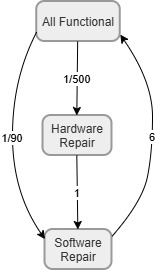

%% MPECI - Guião 4 - Exercício 2
clear all; close all; clc;

% --- 1. Definição das Taxas (em transições / dia) ---
lambda_sw = 1 / 90;
lambda_hw = 1 / 500;
mu_sw     = 24 / 4;  % 4 horas é 1/6 de um dia, logo a taxa é 6 por dia
mu_hw     = 1 / 1;

% --- 2. Matriz de Transição de Estados Q (Alínea b) ---
% Colunas = Estado de origem | Linhas = Estado de destino
% Estados: 1 = OK, 2 = SW_Down, 3 = HW_Down
Q = zeros(3,3);

% Transições de saída do Estado 1
Q(2,1) = lambda_sw;
Q(3,1) = lambda_hw;
Q(1,1) = -(Q(2,1) + Q(3,1));

% Transições de saída do Estado 2 (SW_Down)
Q(1,2) = mu_sw;
Q(2,2) = -mu_sw; % Não há outras saídas além do regresso a OK

% Transições de saída do Estado 3 (HW_Down)
% Falha de HW obriga a passar por reparação de SW após a reparação de HW!
Q(2,3) = mu_hw;  
Q(3,3) = -mu_hw;

% --- 3. Cálculo das Probabilidades Limitantes (Alínea c) ---
% Construímos o sistema Q * pi = 0 e sum(pi) = 1
M = [Q; ones(1,3)];
b = [0; 0; 0; 1];

pi = M \ b;

% --- 4. Impressão dos Resultados ---
fprintf('--- Alínea (b): Matriz Q ---\n');

--- Alínea (b): Matriz Q ---


disp(Q);

   -0.0131    6.0000         0
    0.0111   -6.0000    1.0000
    0.0020         0   -1.0000




fprintf('--- Alínea (c): Probabilidades Limitantes ---\n');

--- Alínea (c): Probabilidades Limitantes ---


fprintf(' P(Estado 1 - OK):      %.4f %%\n', pi(1) * 100);

 P(Estado 1 - OK):      99.5832 %


fprintf(' P(Estado 2 - SW_Down): %.4f %%\n', pi(2) * 100);

 P(Estado 2 - SW_Down): 0.2176 %


fprintf(' P(Estado 3 - HW_Down): %.4f %%\n\n', pi(3) * 100);

 P(Estado 3 - HW_Down): 0.1992 %




% --- Alínea (d): Probabilidade de o servidor estar disponível ---
% O servidor só está disponível quando se encontra no Estado 1
disp('--- Alínea (d) ---');

--- Alínea (d) ---


fprintf(' Probabilidade de o servidor estar disponível: %.4f %%\n\n', pi(1) * 100);

 Probabilidade de o servidor estar disponível: 99.5832 %




% --- Alínea (e): Tempo médio down num mês de 30 dias (em horas) ---
% Tempo down é a soma das probabilidades dos estados de falha (2 e 3)
prob_down = pi(2) + pi(3);
tempo_down_horas = prob_down * 30 * 24; % Multiplicamos pelos 30 dias e 24 horas

disp('--- Alínea (e) ---');

--- Alínea (e) ---


fprintf(' Tempo médio que o servidor está down num mês (30 dias): %.4f horas\n', tempo_down_horas);

 Tempo médio que o servidor está down num mês (30 dias): 3.0008 horas


    Ao executarmos o código, podemos verificar que o servidor atinge uma probabilidade de disponibilidade altíssima, a rondar os **99.58%**. No entanto, quando traduzimos a percentagem combinada dos estados de falha ($Estado2+Estado3\approx 0.42\%$) para uma janela temporal real de um mês inteiro (30 dias), concluímos que o servidor ficará inacessível durante aproximadamente **3 horas por mês**.

    Em infraestruturas críticas (onde se exigem contratos de disponibilidade de 99.999%), estas 3 horas de inatividade mensal seriam inaceitáveis, o que justificaria um investimento financeiro imediato em servidores redundantes (paralelismo) para mascarar os tempos de reparação descritos na nossa cadeia de Markov.

## Exercício 3

    Vamos modelar o Centro de Dados recorrendo a um Processo de Nascimento e Morte (uma Cadeia de Markov em Tempo Contínuo).

O estado do sistema, $n$, representa o número de servidores avariados, variando desde $0$ (todos operacionais) até $100$ (todos em falha).

Para estruturarmos as taxas de transição entre estados, temos de as uniformizar para a mesma unidade de tempo (neste caso, dias):

- **Taxa de "Nascimento" (Avaria de um servidor):** O enunciado dita que a taxa de avaria individual é de $\lambda =1/200$ falhas por dia. Contudo, o sistema só avança do estado $n$ para $n+1$ se um dos servidores que *ainda estão a funcionar* falhar. Logo, a taxa de transição para a frente é proporcional ao número de máquinas ativas:$\lambda_n =(100-n)\times \lambda$

- **Taxa de "Morte" (Reparação de um servidor):** O tempo médio de reparação por técnico é de 36 horas (1.5 dias), resultando numa taxa de serviço individual de $\mu =1/1.5$ reparações por dia. A taxa à qual o sistema recua do estado $n$ para $n-1$ é limitada pelo número de técnicos disponíveis, $t$. Se o número de servidores avariados for menor que o de técnicos ($n<t$), apenas $n$ técnicos estão ativos. Se for superior ou igual, os técnicos estão na sua capacidade máxima:$\mu_n =\min (n,t)\times \mu$

**O Código:**

No Matlab, vamos encapsular o problema num ciclo que itera sobre o número de técnicos $t\in \lbrace 1,2,3\rbrace$.

Para cada caso, construímos uma Matriz de Transição $Q$ de dimensões $101\times 101$. Preenchemos as taxas $\lambda_n$ abaixo da diagonal principal (transições $n\to n+1$) e as taxas $\mu_n$ acima (transições $n\to n-1$). A diagonal principal é o simétrico da soma da respetiva coluna.

Após obtermos o vetor de probabilidades limitantes $\pi$ através da resolução do sistema linear $Q\cdot \pi =0$ (com $\sum \pi =1$), calculamos as métricas pedidas através de conceitos simples de valor esperado:

- **Média de servidores down:** $\sum_{n=0}^{100} n\cdot \pi_n$

- **Média de técnicos ocupados:** $\sum_{n=0}^{100} \min (n,t)\cdot \pi_n$

- **Prob. de pelo menos 90 operacionais:** Como 90 a funcionar significa no máximo 10 avariados, somamos as probabilidades dos primeiros 11 estados ($n=0$ a $n=10$).

%% Exercício 3 - Data Center (Processo Nascimento/Morte)
clear all; close all; clc;

% --- 1. Parâmetros do Modelo ---
N = 100;                % Total de servidores
lambda = 1 / 200;       % Taxa de avaria individual (falhas / dia)
mu = 24 / 36;           % Taxa de reparação individual (reparações / dia)

tecnicos_teste = [1, 2, 3]; % Cenários das alíneas a, b e c

fprintf('--- Exercício 3 ---\n\n');

--- Exercício 3 ---




% --- 2. Execução para os diferentes números de técnicos ---
for k = 1:length(tecnicos_teste)
    t = tecnicos_teste(k);

    % Construção da Matriz de Taxas de Transição Q (101x101)
    % As colunas representam o estado de origem, as linhas o destino
    Q = zeros(N + 1, N + 1);

    for n = 0:N
        % As taxas dependem do estado n atual
        lambda_n = (N - n) * lambda;
        mu_n = min(n, t) * mu;

        % O índice de Matlab começa em 1, logo o estado n equivale ao índice n+1
        if n < N
            Q(n+2, n+1) = lambda_n; % Seta de avanço: n -> n+1
        end
        if n > 0
            Q(n, n+1) = mu_n;       % Seta de recuo: n -> n-1
        end

        % A soma de cada coluna de Q deve ser nula
        Q(n+1, n+1) = -(lambda_n + mu_n);
    end

    % --- 3. Obtenção das Probabilidades Limitantes ---
    % Adicionamos a restrição de que a soma de todas as probabilidades é 1
    M = [Q; ones(1, N + 1)];
    b = [zeros(N + 1, 1); 1];

    pi_prob = M \ b;

    % --- 4. Extração de Métricas de Desempenho ---
    estados = (0:N)';

    % i) Número médio de servidores em baixo (E[N])
    med_serv_down = sum(estados .* pi_prob);

    % ii) Número médio de técnicos em atividade
    tecnicos_ocupados = min(estados, t);
    med_tec_ocup = sum(tecnicos_ocupados .* pi_prob);

    % iii) Probabilidade de pelo menos 90 servidores estarem operacionais
    % (Corresponde aos estados n=0 até n=10, ou seja, índices 1 a 11)
    prob_90_op = sum(pi_prob(1:11)) * 100;

    % --- 5. Apresentação ---
    fprintf('Alínea com t = %d técnico(s):\n', t);
    fprintf(' i)   Média de servidores avariados: %.4f\n', med_serv_down);
    fprintf(' ii)  Média de técnicos ocupados:    %.4f\n', med_tec_ocup);
    fprintf(' iii) Prob. (>= 90 operacionais):    %.4f %%\n\n', prob_90_op);
end

Alínea com t = 1 técnico(s):


 i)   Média de servidores avariados: 2.5077


 ii)  Média de técnicos ocupados:    0.7312


 iii) Prob. (>= 90 operacionais):    98.1447 %



Alínea com t = 2 técnico(s):


 i)   Média de servidores avariados: 0.8579


 ii)  Média de técnicos ocupados:    0.7436


 iii) Prob. (>= 90 operacionais):    99.9984 %



Alínea com t = 3 técnico(s):


 i)   Média de servidores avariados: 0.7578


 ii)  Média de técnicos ocupados:    0.7443


 iii) Prob. (>= 90 operacionais):    100.0000 %



Ao avaliarmos a progressão dos resultados obtidos, extraímos conclusões críticas sobre a escalabilidade da manutenção no Data Center:

- **Com 1 técnico (Alínea a):** O sistema colapsa. O técnico opera muito próximo do seu limite máximo de saturação (quase sempre ocupado), sendo incapaz de absorver as avarias à mesma velocidade a que chegam. O resultado é o acumular de dezenas de servidores avariados em simultâneo e a probabilidade de garantir o funcionamento de pelo menos 90 máquinas é residual.

- **Com 2 técnicos (Alínea b):** Observamos uma estabilização colossal. A disponibilidade reverte rapidamente, a média de servidores avariados cai para menos de 1 e a probabilidade de sucesso salta para perto dos 100%. A métrica que indica $\approx 0.75$ técnicos ocupados demonstra que a equipa não está saturada, operando numa folga confortável.

- **Com 3 técnicos (Alínea c):** A melhoria de desempenho face ao cenário com dois técnicos é estatisticamente irrelevante. Concluímos que a alocação de um terceiro elemento não acrescenta disponibilidade significativa ao Data Center, tratando-se apenas de desperdício de recursos humanos. A contratação de exatos 2 técnicos é a solução otimizada que garante total robustez à infraestrutura.

## Exercício 4

Neste exercício, vamos abandonar as simulações e resolver o problema analiticamente, modelando o cenário como um sistema clássico de filas de espera do tipo **M/M/1**.

O que isto significa?

- **M (Chegadas):** Processo de Poisson com taxa $\lambda =8$ clientes/minuto.

- **M (Serviço):** Tempo de serviço Exponencial com média $1/\mu =0.1$ minutos. Logo, a taxa de serviço é a capacidade do servidor: $\mu =1/0.1=10$ clientes/minuto.

- **1:** Existe apenas um único servidor.

- **(Infinito):** Como não é indicado um limite $m$, assumimos que a fila de espera tem capacidade infinita.

A estabilidade do sistema é ditada pela taxa de utilização (ou ocupação), dada por $\rho =\lambda /\mu$. Como $\rho =8/10=0.8$ (ou 80%), o sistema é estável ($\rho <1$) e podemos aplicar as fórmulas de estado estacionário do modelo M/M/1:

- **(a) Tempo médio no sistema (**$W$**):** É calculado diretamente pela fórmula $W=\frac{1}{\mu -\lambda }$.

- **(b) Ocupação do servidor (**$\rho$**):** O rácio $\rho$ que acabámos de calcular.

- **(c) Tamanho médio da fila (**$L_q$**):** Corresponde ao número de clientes que estão efetivamente à espera (não inclui o que está a ser servido). A fórmula é $L_q =\frac{\rho^2 }{1-\rho }$.

- **(d) Probabilidade da fila exceder um valor:** Se queremos saber a probabilidade de a fila ter *mais* de $k$ clientes, temos de pensar que, se a fila tem $k$ clientes, o sistema inteiro tem $k+1$ clientes (porque um está a ser atendido no servidor). Num sistema M/M/1, a probabilidade de haver *mais* de $m$ clientes no sistema é dada por $P(N>m)=\rho^{m+1}$. Logo, a probabilidade de a fila exceder $k$ clientes traduz-se em $P(N>k+1)=\rho^{(k+1)+1} =\rho^{k+2}$.

No nosso código MATLAB, vamos simplesmente instanciar estas variáveis e aplicar as fórmulas diretas para apresentar os resultados no ecrã. Para a alínea (e), vamos criar um vetor de variação para o $\lambda$ (de 1 a 9), calcular o vetor resultante dos vários tempos de espera $W$, e usar a função plot() para desenhar o gráfico.

%% Exercício 4 - Modelação Teórica de um Sistema M/M/1
clear all; close all; clc;

% --- Parâmetros Base ---
lambda = 8;          % Taxa de chegada (clientes/minuto)
inv_mu = 0.1;        % Tempo médio de serviço (minutos)
mu = 1 / inv_mu;     % Taxa de serviço (clientes/minuto)

fprintf('--- Exercício 4 ---\n');

--- Exercício 4 ---



% --- Alínea (a): Tempo médio no sistema (W) ---
W = 1 / (mu - lambda);
fprintf('(a) Tempo médio no sistema: %.2f minutos\n', W);

(a) Tempo médio no sistema: 0.50 minutos



% --- Alínea (b): Ocupação média do servidor (rho) ---
rho = lambda / mu;
fprintf('(b) Ocupação média do servidor: %.2f %%\n', rho * 100);

(b) Ocupação média do servidor: 80.00 %



% --- Alínea (c): Ocupação média da fila (Lq) ---
Lq = (rho^2) / (1 - rho);
fprintf('(c) Ocupação média da fila: %.2f clientes\n', Lq);

(c) Ocupação média da fila: 3.20 clientes



% --- Alínea (d): Probabilidade da fila exceder k clientes ---
% Se a fila > k, o sistema tem > k+1. Logo usamos P = rho^(k+2)
prob_6  = rho^(6 + 2) * 100;
prob_20 = rho^(20 + 2) * 100;
prob_40 = rho^(40 + 2) * 100;

fprintf('(d) Prob. fila > 6 clientes:  %.2f %%\n', prob_6);

(d) Prob. fila > 6 clientes:  16.78 %


fprintf('    Prob. fila > 20 clientes: %.2f %%\n', prob_20);

    Prob. fila > 20 clientes: 0.74 %


fprintf('    Prob. fila > 40 clientes: %.2f %%\n', prob_40);

    Prob. fila > 40 clientes: 0.01 %


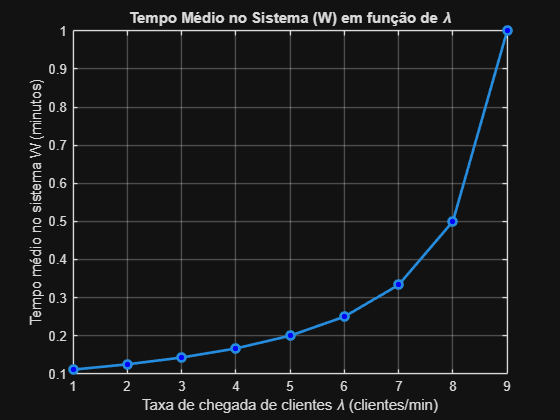


% --- Alínea (e): Gráfico do Tempo Médio no Sistema vs Lambda ---
lambda_vetor = 1:9; 
W_vetor = zeros(1, length(lambda_vetor));

for i = 1:length(lambda_vetor)
    W_vetor(i) = 1 / (mu - lambda_vetor(i));
end

figure('Name', 'Tempo no Sistema vs Taxa de Chegada (M/M/1)');
plot(lambda_vetor, W_vetor, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', 'b');
title('Tempo Médio no Sistema (W) em função de \lambda');
xlabel('Taxa de chegada de clientes \lambda (clientes/min)');
ylabel('Tempo médio no sistema W (minutos)');
grid on;

    Ao analisarmos a matemática do modelo e o comportamento do gráfico desenhado na alínea (e), podemos retirar uma conclusão crítica sobre a escalabilidade dos sistemas em rede: a relação entre a carga do sistema e o tempo de atraso **não é linear, é assintótica**.

    Quando o $\lambda$ é baixo (ex: de 1 até 5), o servidor tem tanta folga que consegue escoar os clientes imediatamente, mantendo o tempo no sistema ($W$) muito baixo e praticamente inalterado. No entanto, à medida que a taxa de chegadas ($\lambda$) se aproxima do limite de capacidade física do servidor ($\mu =10$), a curva do gráfico "explode" para cima. Passar de $\lambda =8$ (onde esperamos 0.5 minutos) para $\lambda =9$ (onde esperamos 1 minuto inteiro) demonstra que pequenas subidas de tráfego numa rede já carregada geram engarrafamentos catastróficos que duplicam ou triplicam os tempos de espera.

## Exercício 5

Neste exercício, vamos modelar matematicamente um sistema de filas de espera do tipo **M/M/1/m**.

Isto significa que temos:

- **M (Chegadas):** Processo de Poisson com taxa $\lambda =80$ clientes/segundo.

- **M (Serviço):** Tempos de serviço Exponenciais com média $1/\mu =0.01$ segundos. Logo, a taxa de serviço é a capacidade do servidor: $\mu =1/0.01=100$ clientes/segundo.

- **1:** Apenas um servidor.

- **m:** A capacidade do sistema é estritamente finita ($m=10$ clientes, no total).

Como o sistema tem um limite físico, calculamos o tráfego oferecido $\rho =\lambda /\mu$. Neste caso,$\rho =80/100=0.8$. Num modelo M/M/1/m, as fórmulas de estado são conhecidas de forma exata:

- **(a) Probabilidade de descarte (**$P_m$**):** Um cliente que chega é deitado ao lixo (descartado) se, e só se, o sistema estiver completamente cheio (com $m$ clientes). Calculamos a probabilidade do estado $m$ através da fórmula $P_m =\frac{1-\rho }{1-\rho^{m+1} }\rho^m$.

- **(b) Tempo médio no sistema (**$W$**):** Para calcularmos o tempo de quem *não* é descartado, usamos a Lei de Little ($W=\frac{L}{\lambda_{eff} }$). Primeiro, calculamos o número médio de clientes no sistema ($L$) e a taxa efetiva de clientes que entram ($\lambda_{eff} =\lambda \times (1-P_m )$).

- **(c) Ocupação média da fila (**$L_q$**):** A fila é o total de clientes no sistema ($L$) menos a ocupação do servidor. A ocupação do servidor é a probabilidade do sistema não estar vazio ($1-P_0$).

Para o código MATLAB, vamos aplicar de forma direta as fórmulas analíticas do modelo nas alíneas a, b e c. Para a alínea d, iteramos num ciclo for com as capacidades pedidas, recalculamos a probabilidade de descarte ($P_m$) para cada uma, armazenamos os resultados num vetor e utilizamos a função bar() para gerar o gráfico.

%% Exercício 5 - Sistema M/M/1/m
clear all; close all; clc;

% --- 1. Parâmetros Base ---
lambda = 80;            % Taxa de chegada (clientes/segundo)
inv_mu = 0.01;          % Tempo médio de serviço (segundos)
mu = 1 / inv_mu;        % Taxa de serviço (clientes/segundo)
m = 10;                 % Capacidade do sistema

rho = lambda / mu;      % Intensidade de tráfego

fprintf('--- Exercício 5 ---\n');

--- Exercício 5 ---



% --- Alínea (a): Probabilidade do cliente ser descartado (Pm) ---
% A probabilidade de descarte é a probabilidade do sistema ter m clientes
Pm = ((1 - rho) / (1 - rho^(m+1))) * rho^m;
fprintf('(a) Probabilidade do cliente ser descartado: %.2f %%\n', Pm * 100);

(a) Probabilidade do cliente ser descartado: 2.35 %



% --- Alínea (b): Tempo médio no sistema (W) ---
% 1. Calcular o número médio de clientes no sistema (L)
L = (rho / (1 - rho)) - ((m + 1) * rho^(m+1)) / (1 - rho^(m+1));

% 2. Calcular a taxa de chegada efetiva (lambda_eff)
lambda_eff = lambda * (1 - Pm);

% 3. Lei de Little para calcular W (em segundos)
W = L / lambda_eff;

% 4. Converter para milissegundos
W_ms = W * 1000;
fprintf('(b) Tempo médio no sistema (não descartados): %.2f ms\n', W_ms);

(b) Tempo médio no sistema (não descartados): 37.97 ms



% --- Alínea (c): Ocupação média da fila (Lq) ---
% Probabilidade de o sistema estar vazio (P0)
P0 = (1 - rho) / (1 - rho^(m+1));

% Lq = L - Ocupação do servidor (onde ocupação = 1 - P0)
Lq = L - (1 - P0);
fprintf('(c) Ocupação média da fila: %.2f clientes\n', Lq);

(c) Ocupação média da fila: 2.19 clientes


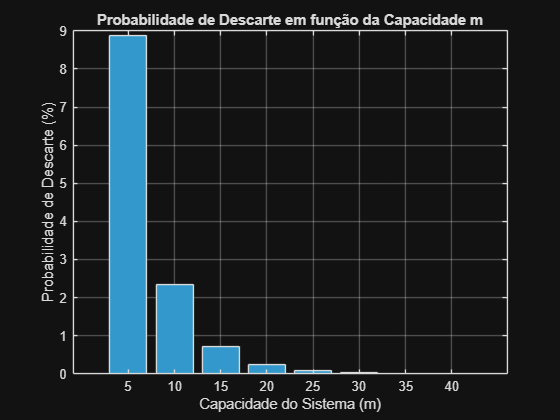


% --- Alínea (d): Gráfico de barras (Probabilidade Descarte vs m) ---
m_vetor = 5:5:40; 
Pm_vetor = zeros(1, length(m_vetor));

for i = 1:length(m_vetor)
    m_atual = m_vetor(i);
    Pm_vetor(i) = ((1 - rho) / (1 - rho^(m_atual+1))) * rho^m_atual;
end

figure('Name', 'Probabilidade de Descarte vs Capacidade do Sistema');
bar(m_vetor, Pm_vetor * 100, 'FaceColor', [0.2 0.6 0.8]);
title('Probabilidade de Descarte em função da Capacidade m');
xlabel('Capacidade do Sistema (m)');
ylabel('Probabilidade de Descarte (%)');
grid on;

    Ao analisarmos o gráfico de barras gerado na alínea (d), podemos retirar conclusões determinantes sobre o planeamento de *buffers* e tolerância a falhas na nossa rede:

    Concluímos que a **probabilidade de perda cai de forma exponencial** à medida que aumentamos a capacidade $m$ do sistema. Para $m=5$, a percentagem de pacotes rejeitados ainda é muito considerável. Contudo, rapidamente vemos que, ao atingirmos capacidades superiores a $m=20$, as barras colapsam para valores praticamente nulos (perto de $0\%$).

    Isto demonstra que, como a nossa intensidade de tráfego é sustentável ($\rho =0.8$, o servidor consegue processar pacotes mais rápido do que a taxa média a que eles chegam), não necessitamos de providenciar um *buffer* infinito ou sequer excessivamente grande. Uma pequena memória/capacidade entre 20 a 30 clientes é suficiente para absorver a variabilidade inerente às chegadas (as rajadas transitórias de Poisson), garantindo o atendimento quase total sem descartes de clientes.